## Shooting

x0=0;
L=10;
hp=0.01;
Ta=20;
T0=40;
TL=200;
f=@(x,Tz) [Tz(2);hp*(Tz(1)-Ta)];
x1=odeShooting(f,T0,x0,L,2,10)

x1 = 168.3797

x2=odeShooting(f,T0,x0,L,2,20)

x2 = 285.8980

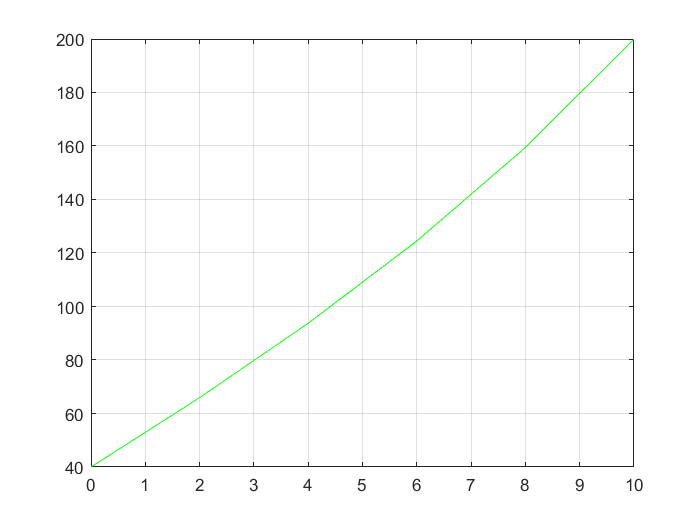

g=@(z) odeShooting(f,T0,x0,L,2,z)-TL;
zresp=biseccion(g,10,20);
Tz0=[40,zresp];
[x,T]=odeRK4(f,Tz0,x0,L,2);
plot(x,T(1,:),'g')
grid on

## Diferencias finitas

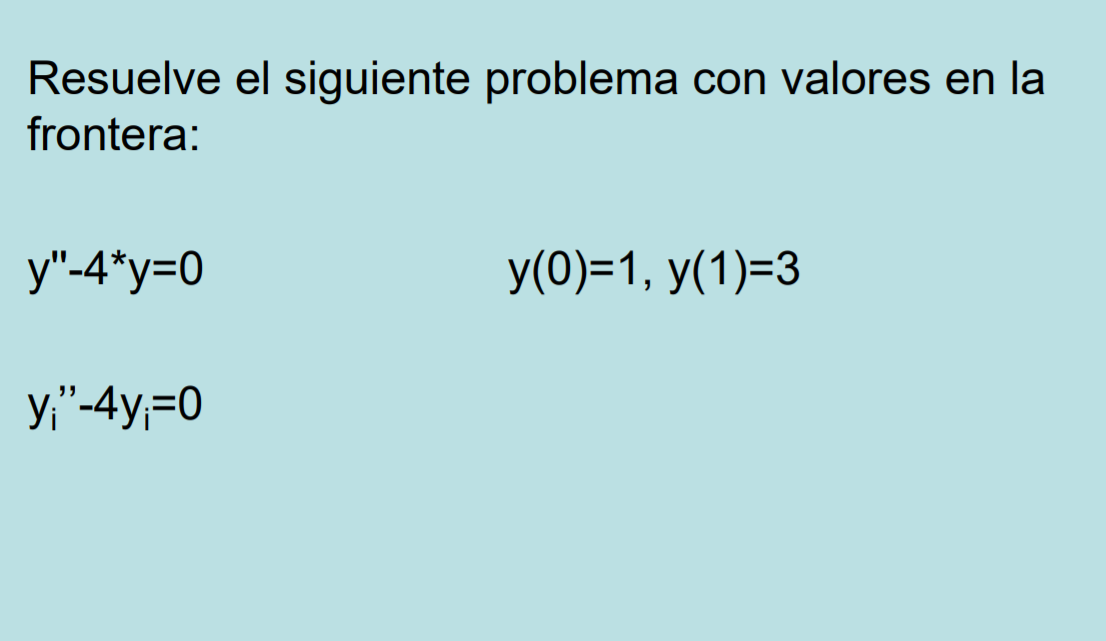

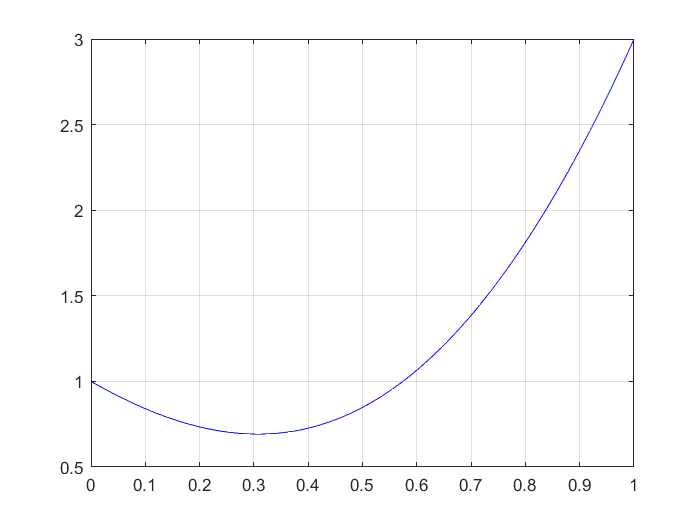

ya = 1;
yb = 3;
n = 100;
x0 = 0;
xf = 1;
h = (xf-x0)/(n-1);
hp = 4;
 %porque ya tenemos el de los valores frontera
A = eye(n-2)*(1)*(4*h^2 + 2);
A(1,2) = -1;
for i=2:n-2
    A(i,i-1) = -1;
    if i~=n-2
        A(i,i+1) = -1;
    end
end

t=x0:h:xf;
b=zeros(n-2,1);%Se podría declarar con el valor que queda del lado derecho como b=eye(n-2,1)*K donde K sea lo que queda en el lado derecho de la ecuación.
b(1,1)=ya;%Aquí se le sumaría lo que quedara del lado derecho de la ec (ya+b(1,1)), pero en este caso es 0.
b(n-2,1)= yb;% Lo mesmo pero con otros índices.
y(1)=ya;
y(n)=yb;
y(2:n-1)=gaussSeidel4(A,b); %Del 2 al 99.
plot(t,y,'b')
grid on

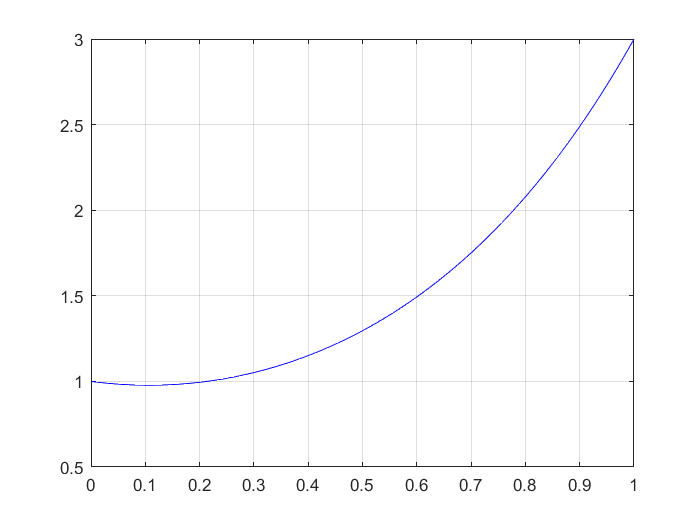

ya = 1;
yb = 3;
n = 100;
x0 = 0;
xf = 1;
h = (xf-x0)/(n-1);
hp = 4;
 %porque ya tenemos el de los valores frontera
A = eye(n-2)*(1)*(4*h^2 + 2);
d = diag(A);
l = zeros(length(d),1)-1;
u = zeros(length(d),1)-1;
t=x0:h:xf;
b=zeros(n-2,1);%Se podría declarar con el valor que queda del lado derecho como b=eye(n-2,1)*K donde K sea lo que queda en el lado derecho de la ecuación.
b(1,1)=ya;%Aquí se le sumaría lo que quedara del lado derecho de la ec (ya+b(1,1)), pero en este caso es 0.
b(n-2,1)= yb;% Lo mesmo pero con otros índices.
y(1)=ya;
y(n)=yb;
y(2:n-1)=tridiagonal_vectores(u,l,d,b); %Del 2 al 99.
plot(t,y,'b')
grid on

ya = 1;
yb = 3;
n = 100;
x0 = 0;
xf = 1;
h = (xf-x0)/(n-1);
e=-1*ones(1,n);
f=2*ones(1,n);
g=-1*ones(1,n);

c=4*h^2;
C=c*ones(1,n);
f=f+C;


r=zeros(n,1);
r(1)=ya;
r(end)=yb;

yTr=tridiagonal_vectores(g,e,f,r);
t=x0:h:xf;
t

t =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


[ya;yTr;yb]

ans =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


plot(t,[ya;yTr;yb])

Error using plot
Vectors must be the same length.

a=0;
b=1;
ya=1;
yb=3;
n=100; %Número de puntos totales
h=(b-a)/(n-2+1); %El denominador es el número de intervalos, es el total de puntos, -2 frontera +1 intervalo externo.
t=a:h:b; %Da n puntos
y=zeros(length(t),1); %Vector columna
% y''(i)=4*y(i) --> y(i-1)+y(i)*(-2-4*h^2)+y(i+1)=0 con las ecuaciones
% y''(i)=[y(i-1)-2y(i)+y(i+1)]/h^2.
%El siguiente for construye la matriz.
M=zeros(n-2);
for i=1:n-2
    r=zeros(1,n-2);
    if i==1
        r(1)=-2-4*h^2;
        r(2)=1;
        M(1,:)=r(1,:);
    else
        if i==(n-2)
            r(n-2)=-2-4*h^2;
            r(n-3)=1;
            M(n-2,:)=r(1,:);
        else
            r(1,i)=-2-4*h^2;
            r(1,i-1)=1;
            r(1,i+1)=1;
            M(i,:)=r(1,:);
        end
    end
end
M

M =    -2.0004    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000   -2.0004    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

ans = 98×98 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

b=zeros(n-2,1);%Se podría declarar con el valor que queda del lado derecho como b=eye(n-2,1)*K donde K sea lo que queda en el lado derecho de la ecuación.
b(1,1)=-ya;%Aquí se le sumaría lo que quedara del lado derecho de la ec (ya+b(1,1)), pero en este caso es 0.
b(n-2,1)=-yb;% Lo mesmo pero con otros índices.
y(1)=ya;
y(n)=yb;
y(2:n-1)=gaussSeidel4(M,b); %Del 2 al 99.
plot(t,y,'b')
grid on